extCoeffFile = 'J:\temp\prahl_extinct_coef.txt';

load('J:\temp\sample.mat'); % xform_hb, xform_fluor
% xform_hb is in mmol/liter
% xform_fluor is ratio change from baseline

blueWavelength = 454; % nm
greenWavelength = 512;

Getting optical properties

[lambda, extCoeff]=mouseAnalysis.expSpecific.getHb(extCoeffFile);

blueLambdaInd = find(lambda == blueWavelength);
greenLambdaInd = find(lambda == greenWavelength);

hbOAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],1);
hbRAbsCoeff = extCoeff([blueLambdaInd greenLambdaInd],2);

Hb correction

fluorCorr = mouseAnalysis.physics.correctHb(xform_fluor,xform_hb,...
    hbOAbsCoeff,hbRAbsCoeff);


Plot

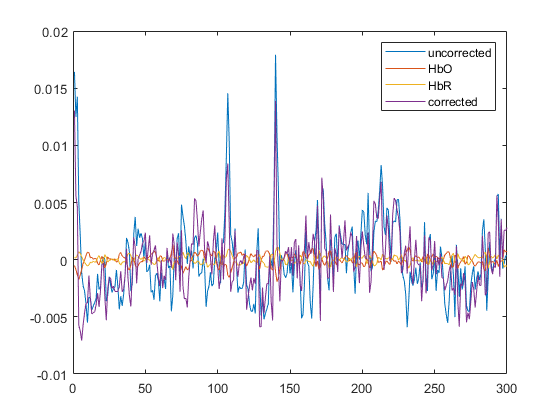

plot(squeeze(xform_fluor(30,80,1,:)))
hold on;
plot(squeeze(xform_hb(30,80,1,:)))
plot(squeeze(xform_hb(30,80,2,:)))
plot(squeeze(fluorCorr(30,80,1,:)))
legend('uncorrected','HbO','HbR','corrected')
hold off;